# Simple data import

To open this page as a Matlab live script, run the command

If you would like to use this page to build your own m-file , get started by running this command

This tutorial shows how to import fluorescence and absorbance data with file triplets (sample EEM, blank EEM, absorbance spectrum). The particular dataset imported here was measured on an Horiba AquaLog.

## Toolbox setup

clearvars
close all force
cd(fileparts(matlab.desktop.editor.getActiveFilename))
tbx=drEEMtoolbox;

This clears all old variables (should they exist), closes all figures (if they exist) and changes the directory to the directory of this tutorial. Lastly, the toolbox is initialized as an object where it's methds (functions) are accessible via the notation `tbx.functionname`.

## Data download

The demo data is archived seperately as a Zenodo entry. First, we need to download and unzip the data and then change into the created folder to access the data.

% websave("drEEM-2-importTutorial1Data.zip","https://zenodo.org/records/18324791/files/drEEM-2-importTutorial1Data.zip?download=1");
% unzip("drEEM-2-importTutorial1Data.zip","drEEM-2-importTutorial1Data")
%delete("drEEM-2-importTutorial1Data.zip")
cd('drEEM-2-importTutorial1Data')

Please be a little patient with this step. The data is 50MB and Zenodo connections can be unreliable. If you get an error, simply retry or wait a bit and then try again.

## Data import

Data import is relatively simple once you've found the right settings. In drEEM, [`importeems`](matlab:open('importeems.html')) handles fluorescence data and [`importabsorbance`](matlab:open('importabsorbance.html')) handles absorbance scans. For the import of EEMs, these data are a perfect match with the defaults of drEEM. The EEMs were produced with an Horiba Aqualog, and for this instrument, you won't need to specify any inputs other than the file pattern to watch for.

But before we get to importing, we should talk about the idea of "status". For the toolbox to keep track of things, you'll need to tell it first what the status of a dataset is. For example, are the data spectrally corrected? Has the instrument software subtracted blanks already? The toolbox doesn't know, but you should.  Read more about the status propery in the documentation of [`drEEMstatus`](matlab:open('drEEMstatus.html')).

You have two options regarding this. Either, you just import your data and get asked with a pop-up GUI about this, or you provide the information to the import function upfront. For the samples, I'll show you what happens if you don't supply the information up front:

cd demofiles_AL_HYI
samples=tbx.importeems('* - Waterfall Plot Sample.dat');

1/33: CAMAS01 (01) (0.55 sec. remaining)
2/33: LCEP02 (01) (0.63 sec. remaining)
3/33: LCEP05 (01) (0.45 sec. remaining)
4/33: LCEP08 (01) (0.45 sec. remaining)
5/33: LCEP11 (01) (0.48 sec. remaining)
6/33: LCEP14 (01) (0.53 sec. remaining)
7/33: LCEP20 (01) (0.5 sec. remaining)
8/33: LCEP23 (01) (0.43 sec. remaining)
9/33: LCEP26 (01) (0.41 sec. remaining)
10/33: QS (01) (0.37 sec. remaining)
11/33: TS01 (01) (0.35 sec. remaining)
12/33: TS02 (01) (0.37 sec. remaining)
13/33: TS03 (01) (0.32 sec. remaining)
14/33: TS04 (01) (0.32 sec. remaining)
15/33: TS05 (01) (0.37 sec. remaining)
16/33: TS06 (01) (0.4 sec. remaining)
17/33: TS07 (01) (0.29 sec. remaining)
18/33: TS08 (01) (0.29 sec. remaining)
19/33: TS09 (01) (0.24 sec. remaining)
20/33: TS10 (01) (0.24 sec. remaining)
21/33: TS11 (01) (0.22 sec. remaining)
22/33: TS12 (01) (0.19 sec. remaining)
23/33: TS13 (01) (0.18 sec. remaining)
24/33: TS14 (01) (0.16 sec. remaining)
25/33: TS15 (01) (0.15 sec. remaining)
26/33: TS16 (01) (0

As you can see, there's some console output to keep us updated. After completion, a figure pops up to ask us about the status of the imported samples:

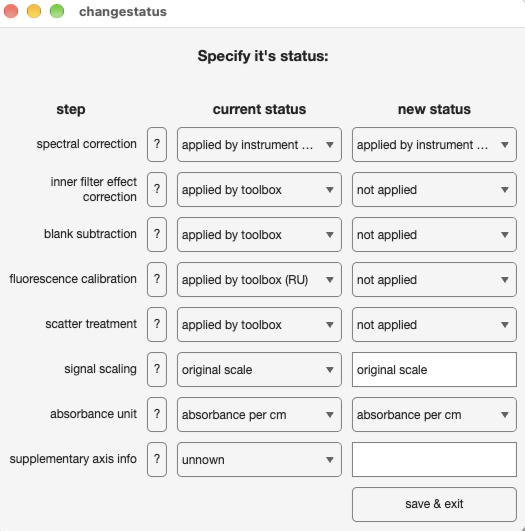

In this case, the default options for the status are appropriate. Note that in your own case, the dataset status might differ and you should use this opportunity to provide the correct information. 

**Note:** When you only import one of the supported data types (e.g., fluorescence, but technically not absorbance since it's seperate), specify 'not applicable (no data)' for the field that has no data or specify what might apply in the future if you transfer the data yourself. If you use mergemeasurements.m later on to transfer the data, the absorbanceUnit status only needs to be correct for the dataset that actually contains absorbance (not the two fluorescence datasets).

**For the blank**, let's demonstrate a different way of providing the dataset's status. We will initialize a drEEMstatus object and explicitly specify the properties. Note that at this stage, you *could* also copy the samples.status object since you provided the right input for all three different datasets we're working with. Notice how absorbanceUnit='not applicable (no data)' snice there's no absorbance data?

blanks_status=drEEMstatus("blankSubtraction","not applied",...
    "IFEcorrection","not applied",...
    "signalCalibration","not applied",...
    "scatterTreatment","not applied",...
    "signalScaling",'original scale',...
    'spectralCorrection','applied by instrument software',...
    absorbanceUnit='not applicable (no data)');
% Make sure to set "absorbanceUnit" to the appropriate status if you plan
% on transfering the variables yourself!
% ">> blanks_status = samples.status" would achieve the same (the status is identical in this case)

blanks=tbx.importeems('* - Waterfall Plot Blank.dat',...
    blanks_status);

1/33: CAMAS01 (01) (1.01 sec. remaining)
2/33: LCEP02 (01) (0.78 sec. remaining)
3/33: LCEP05 (01) (0.66 sec. remaining)
4/33: LCEP08 (01) (0.64 sec. remaining)
5/33: LCEP11 (01) (0.71 sec. remaining)
6/33: LCEP14 (01) (0.85 sec. remaining)
7/33: LCEP20 (01) (0.69 sec. remaining)
8/33: LCEP23 (01) (0.59 sec. remaining)
9/33: LCEP26 (01) (1.14 sec. remaining)
10/33: QS (01) (1.9 sec. remaining)
11/33: TS01 (01) (0.7 sec. remaining)
12/33: TS02 (01) (0.74 sec. remaining)
13/33: TS03 (01) (0.48 sec. remaining)
14/33: TS04 (01) (0.58 sec. remaining)
15/33: TS05 (01) (0.57 sec. remaining)
16/33: TS06 (01) (13.32 sec. remaining)
17/33: TS07 (01) (2.38 sec. remaining)
18/33: TS08 (01) (1.07 sec. remaining)
19/33: TS09 (01) (0.92 sec. remaining)
20/33: TS10 (01) (0.71 sec. remaining)
21/33: TS11 (01) (0.68 sec. remaining)
22/33: TS12 (01) (0.54 sec. remaining)
23/33: TS13 (01) (0.37 sec. remaining)
24/33: TS14 (01) (0.18 sec. remaining)
25/33: TS15 (01) (0.16 sec. remaining)
26/33: TS16 (01) (

clearvars blanks_status

Next is absorbance. Since I set the correct status options in the two EEM datasets already, I can just supply one of these to the import function (as I had mentioned before):

absorbance_status=drEEMstatus(absorbanceUnit='absorbance per cm');
% I do not set the rest of the status properties because they are
% irrelenvant
absorbance=tbx.importabsorbance('* - Abs Spectra Graphs.dat',absorbance_status);

1/32: CAMAS01 (01) (0.4 sec. remaining)
2/32: LCEP02 (01) (0.27 sec. remaining)
3/32: LCEP05 (01) (0.24 sec. remaining)
4/32: LCEP08 (01) (0.21 sec. remaining)
5/32: LCEP11 (01) (0.22 sec. remaining)
6/32: LCEP14 (01) (0.21 sec. remaining)
7/32: LCEP20 (01) (0.36 sec. remaining)
8/32: LCEP23 (01) (0.22 sec. remaining)
9/32: LCEP26 (01) (0.23 sec. remaining)
10/32: TS01 (01) (0.22 sec. remaining)
11/32: TS02 (01) (0.16 sec. remaining)
12/32: TS03 (01) (0.13 sec. remaining)
13/32: TS04 (01) (0.12 sec. remaining)
14/32: TS05 (01) (0.11 sec. remaining)
15/32: TS06 (01) (0.13 sec. remaining)
16/32: TS07 (01) (0.11 sec. remaining)
17/32: TS08 (01) (0.09 sec. remaining)
18/32: TS09 (01) (0.11 sec. remaining)
19/32: TS10 (01) (0.09 sec. remaining)
20/32: TS11 (01) (0.07 sec. remaining)
21/32: TS12 (01) (0.06 sec. remaining)
22/32: TS13 (01) (0.05 sec. remaining)
23/32: TS14 (01) (0.06 sec. remaining)
24/32: TS15 (01) (0.06 sec. remaining)
25/32: TS16 (01) (0.04 sec. remaining)
26/32: TS17 (01)

clearvars absorbance_status
cd ..

In general terms, during this import we change the directory to the folder in which the tutorial files are stored. Then, we import the sample EEMs with the relevant file pattern. First the samples, then the blanks. Note that these patterns will be deleted from the filenames in the dataset since they are repetitive and don't have "value" in themselves. Leading or trailing empty characters are also automatically removed. Lastly, the absorbance data gets imported.

This tutorial is referred to as the "simple" data import tutorial since the default settings in the two importing functions fit the file type perfectly. For files with different format, you will have to take a look at different tutorials and / or explore the function documentation for [`importeems`](matlab:open('importeems.html')) and [`importabsorbance`](http://importabsorbance.html). Customization mainly concern the EEM orientation and where the required information is stored in the file(s). On the other hand, the function automatically determines the number of columns and rows to import.

Next, we delete some information from the filenames to demonstrate how this could be done. The string `' (01)'` refers to the first replicate measurement of the sample. In this example, this information is irrelevant and can be deleted. If a sample was remeasured for some reason, a string `' (02)'` remains in the filename to let us know.

samples.filelist=erase(samples.filelist,{' (01)'});
blanks.filelist=erase(blanks.filelist,{' (01)'});
absorbance.filelist=erase(absorbance.filelist,{' (01)'});
samples=tbx.addcomment(samples,"Erased the ' (01)' string pattern from sample names.","newline");

This is a manual dataset modification in the broadest sense. In the spirt of reproducibility and tracability, we leave a comment in the dataset to remind us of what was done.

## Dataset alignment

It is entirely possible that one of the three files went missing in some cases for some samples. Before we continue, we need to make sure that only complete triplets remain in the three datasets. Incomplete triplets will be deleted. This is ensured with the function [`alignsamples`](matlab:open('alignsamples.html')). It compares the contents of the variable `filelist` within each [`drEEMdataset`](matlab:open('dreemdataset.html')) supplied. Again, in the case of the "simple" tutorial here, the filenames are all identical after the import, so this step should not be difficult. But, since this is a potentially troubling step, we can run the operation in diagnostic mode to see what *would* happen to our datasets *if* we assigned an output:

Diagnostic mode, no output will be assigned (no variable was specified)
samples: removed 1 samples with the previous .i: 10
blanks: removed 1 samples with the previous .i: 10
absorbance: No action necessary. All files between supplied datasets had same names.


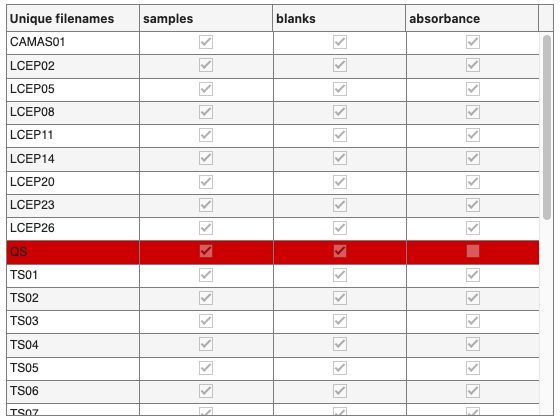

tbx.alignsamples(samples,blanks,absorbance);

The console output let's us know that one sample would be deleted from the EEM sample and blank dataset. What's missing? The absorbance scan. The diagnostics function creates a figure that shows us exactly that. We could go looking for the absorbance scan now. Perhaps reexport the data etc. But here, we will simply delete.

[samples,blanks,absorbance]=tbx.alignsamples(samples,blanks,absorbance);

samples: removed 1 samples with the previous .i: 10
blanks: removed 1 samples with the previous .i: 10
absorbance: No action necessary. All files between supplied datasets had same names.


Now, you can see that one sample was removed in the sample and blank EEM datasets. At this stage, it is safe to transfer the absorbance data into the sample dataset to cut down on the workspace variables:

samples=tbx.mergemeasurements(samples,absorbance,"absorbance");
clearvars absorbance

Note that `mergemeasurements `was first introduced in 2.26.10; earlier versions needed manual transfer. mergemeasurements transfers data, axes, and relevant status properties.

Next, the data comes with a Excel metadata file. Let's bring that table in. We use [`associatemetadata`](matlab:open('associatemetadata.html')) for this task.

samples=tbx.associatemetadata(samples,"metadata.xlsx","sampleId");

                     drEEMdataset    imported metadata table
                     ____________    _______________________

    No. samples           32                   32           
    Total matched         31                   31           
    % matched             97                   97           



 Now we can take a look at the dataset's history with [`displayhistory`](matlab:open('displayhistory.html')) to demonstrate how this could be useful:

tbx.displayhistory(samples)

    #            Function            User comment                                          Function message                                       
    _    ________________________    ____________    _____________________________________________________________________________________________

    1    importeems                       ""         created dataset                                                                              
    2    addcomment: user comment         ""         Erased the ' (01)' string pattern from sample names.                                         
    3    alignsamples                     ""         removed 1 samples with the previous .i: 10                                                   
    4    mergemeasurements                ""         Transfered measurements, axis information, and status of "abs" from "absorb

You could also use the GUI tool [`viewhistory`](matlab:open('viewhistory')) for this:

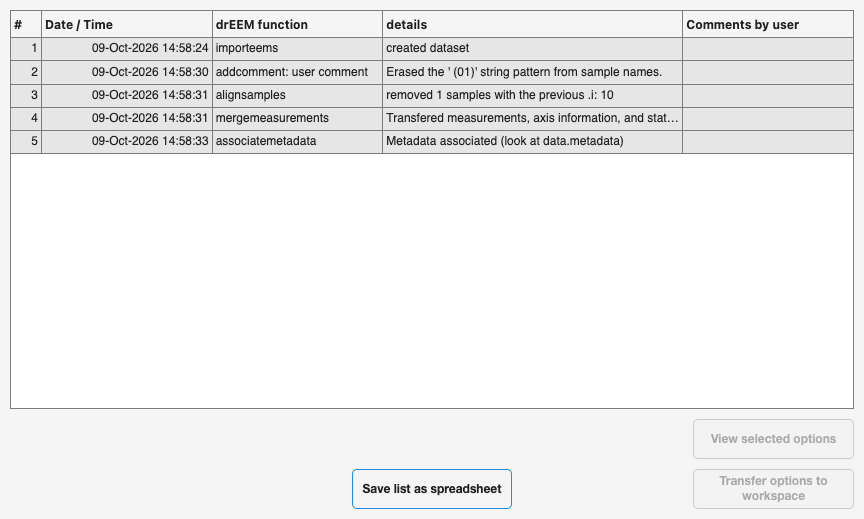

tbx.viewhistory(samples)

The color coding in the GUI tool is designed to distinguish between different functions. I.e. if you called subdataset many times, these lines will have the same color. Now we can save the dataset for later use.

cd ..
save('tutorial_01_imported.mat',"blanks","samples")

Let's keep your installation tidy:

%rmdir("drEEM-2-importTutorial1Data","Recursive",true)
disp('Tutorial finished.')

Tutorial finished.


This is the end of the tutorial. If you want to go further, have a look at the [data processing tutorial](matlab:open('processing_tutorial_01.html')).